## Approximating a Square Wave

## Discrete-time Fourier Series

Plot square wave signal against time

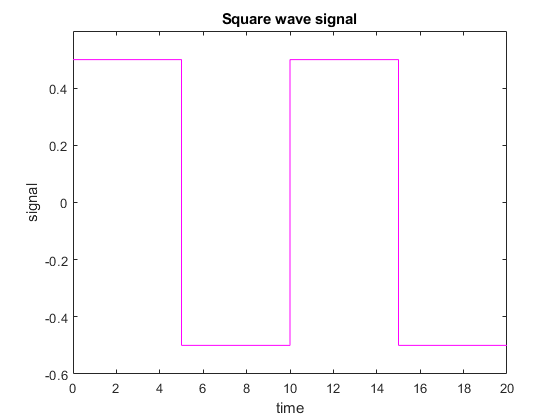

[t, s, b] = generate_data;
plot(t, s, 'm')
xlabel('time')
ylabel('signal')
title('Square wave signal')
ylim([-0.6 0.6])
xlim([0 20])
hold off

How would you numerically test for the orthogonality of the basis vectors (rows of B unnorm)?

Plot the first 6 and 30th basis vectors against time in separate sub-plots that share the same time axis.

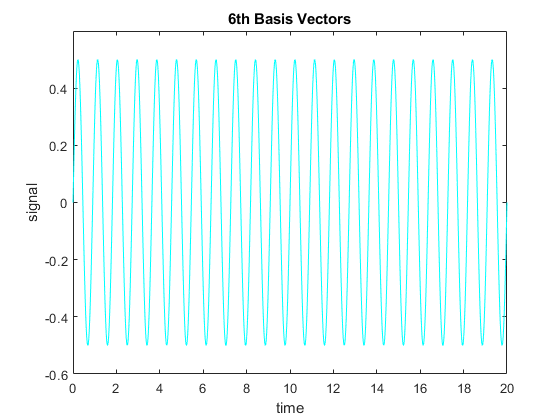

% Numerically test for orthogonality by doing the inner product between all
% vectors that form the basis. 

plot(t, b(6,:), 'c')
xlabel('time')
ylabel('signal')
title('6th Basis Vectors')
ylim([-0.6 0.6])
xlim([0 20])

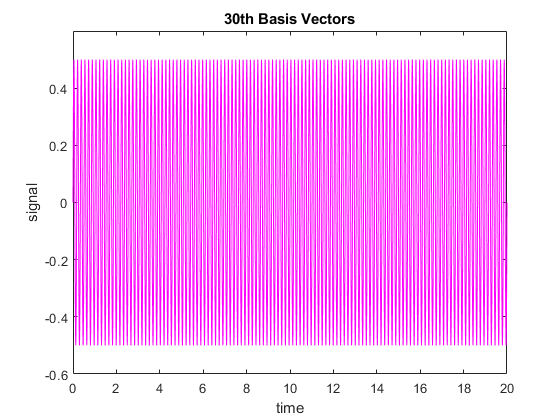


plot(t, b(30,:), 'm')
xlabel('time')
ylabel('signal')
title('30th Basis Vectors')
ylim([-0.6 0.6])
xlim([0 20])

Normalize the given basis vectors to obtain an orthonormal basis. Project the square wave signal onto the normalized basis vectors using l2 projection and compute the projection coefficients. Arrange the basis vectors in the decreasing order of the magnitude of the projection coeffcients. Approximate the square wave using the first 1; 2; 3; 4; 5; 6; 30 basis vectors, and plot the approximations in separate sub-plots that share the same time axis. Plot the original signal on top of each approximation and compare.

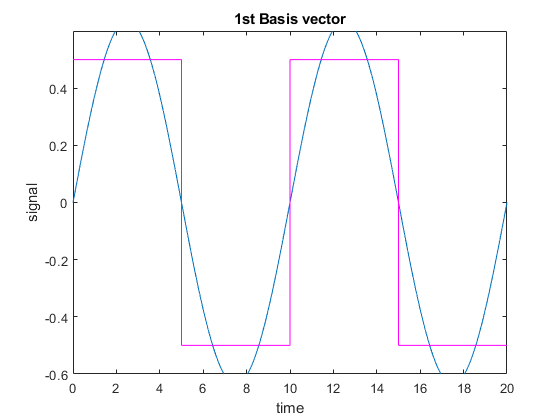

% Normalize vectors (rows)
b_norm = normr(b); % Orthonormal basis
A_1 = b_norm(1, :);
A_2 = b_norm(2, :);
A_3 = b_norm(3, :);
A_4 = b_norm(4, :);
A_5 = b_norm(5, :);
A_6 = b_norm(6, :);
A_30 = b_norm(30, :);

% project
p_1 = dot(s, A_1)*A_1;
p_2 = dot(s, A_2)*A_2;
p_3 = dot(s, A_3)*A_3;
p_4 = dot(s, A_4)*A_4;
p_5 = dot(s, A_5)*A_5;
p_6 = dot(s, A_6)*A_6;
p_30 = dot(s, A_30)*A_30;

% plotting
plot(t, p_1)
title ('1st Basis vector')
xlabel('time')
ylabel('signal')
ylim([-0.6 0.6])
xlim([0 20])
hold on
plot(t, s, 'm')
hold off

## Functions

function [ time_pos , sq_wave , B_unnorm ] = generate_data
    n_comps = 30; period = 10; fundFreq = 1/ period ;
    time_pos = 0:0.0001:2* period ; harmonics = 2*(1: n_comps ) -1;
    sq_wave = floor (0.9* sin (2* pi* fundFreq * time_pos )) +.5; %% generate the signal
    B_unnorm = sin (2* pi* fundFreq *( harmonics .'* time_pos )) /2; %% generate the basis
end